J_xx = 100/12;
J_yy = 85/12;
J_zz = 25/12;
J = diag([J_xx J_yy J_zz])

J =     8.3333         0         0
         0    7.0833         0
         0         0    2.0833


ans = 2

w_z_pure = [0; 0; 2*pi];
K_0 = (1/2)*J_zz*w_z_pure(3)^2;

w_x_pure = [sqrt(2*K_0/J_xx); 0; 0];
w_y_pure = [0; sqrt(2*K_0/J_yy); 0];

## Rotational energy ellipsoid

% calculate semi-axes
a_x = sqrt(2*K_0/J_xx)

a_x = 3.1416

a_y = sqrt(2*K_0/J_yy)

a_y = 3.4075

a_z = sqrt(2*K_0/J_zz)

a_z = 6.2832

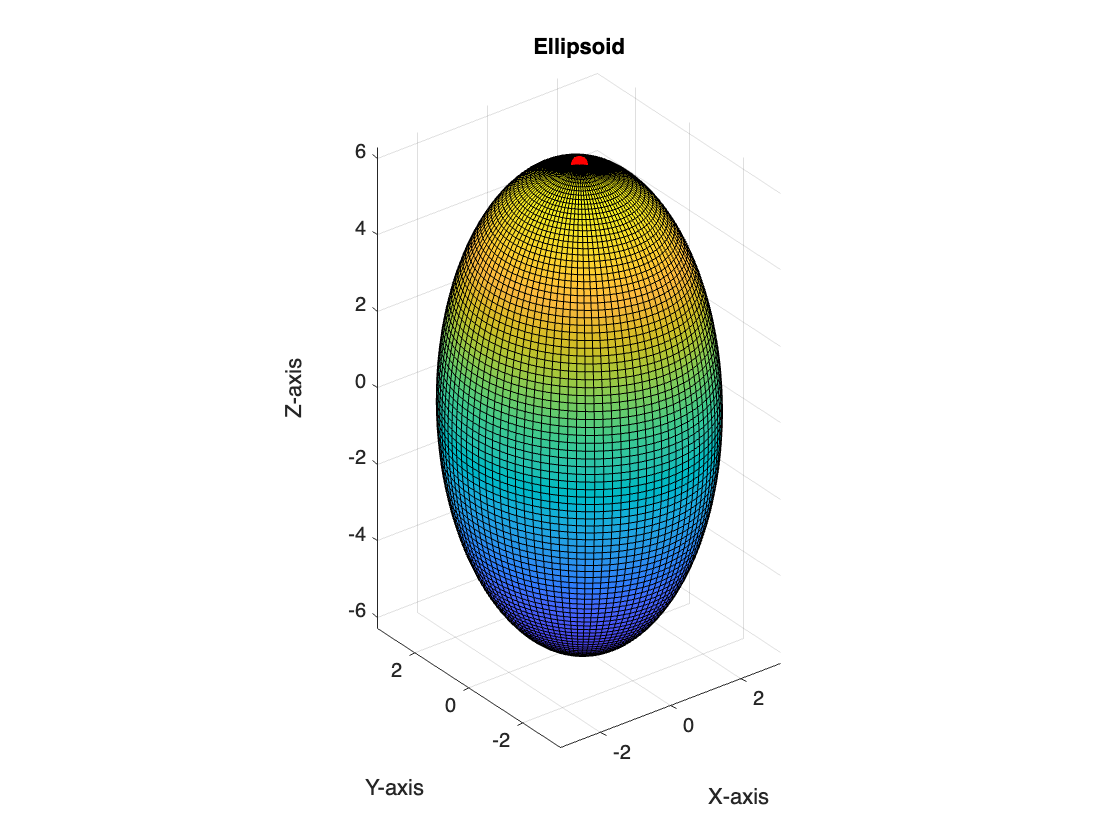

[u, v] = meshgrid(linspace(0, 2*pi, 100), linspace(0, pi, 100));
x_kinetic_ellipsoid = a_x * cos(u) .* sin(v);
y_kinetic_ellipsoid = a_y * sin(u) .* sin(v);
z_kinetic_ellipsoid = a_z * cos(v);
figure;
surf(x_kinetic_ellipsoid, y_kinetic_ellipsoid, z_kinetic_ellipsoid); 
axis equal;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Ellipsoid');
grid on;

px = [w_x_pure(1) w_y_pure(1) w_z_pure(1)];
py = [w_x_pure(2) w_y_pure(2) w_z_pure(2)];
pz = [w_x_pure(3) w_y_pure(3) w_z_pure(3)];

hold on;
plot3(px, py, pz, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); 

## near x-axis:

% valgt 1/100 av ren rotasjon for å overdrive animasjonene
w_z = (1/100)*w_z_pure(3);
w_y = 0;
w_x = w_x_pure(1)*sqrt(1-1/100^2);
w_near_x = [w_x; w_y; w_z];

## near y-axis

w_x = (1/100)*w_x_pure(1);
w_z = 0;
w_y = w_y_pure(2)*sqrt(1-1/100^2);
w_near_y = [w_x; w_y; w_z];

## near z-axis

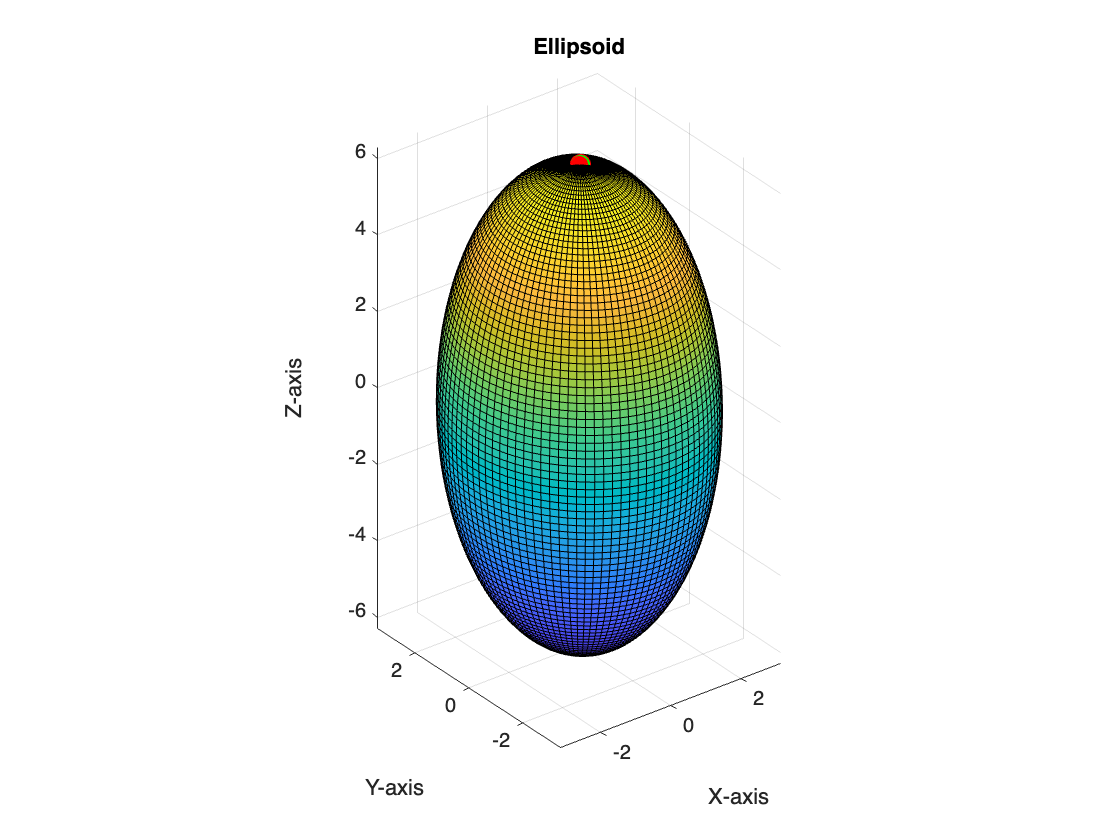

w_x = (1/100)*w_x_pure(1);
w_y = 0;
w_z = w_z_pure(3)*sqrt(1-1/100^2);
w_near_z = [w_x; w_y; w_z];
vecs = [w_near_x w_near_y w_near_z];
plot3(vecs(1,:), vecs(2,:), vecs(3,:), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
hold off;

## Ellipsoids for near x-axis spin

% near x-axis:
h_0 = sqrt(J_xx^2*w_near_x(1)^2 + J_yy^2*w_near_x(2)^2 + J_zz^2*w_near_x(3)^2);

a_x = sqrt(h_0^2/J_xx^2)

a_x = 3.1415

a_y = sqrt(h_0^2/J_yy^2)

a_y = 3.6959

a_z = sqrt(h_0^2/J_zz^2)

a_z = 12.5659

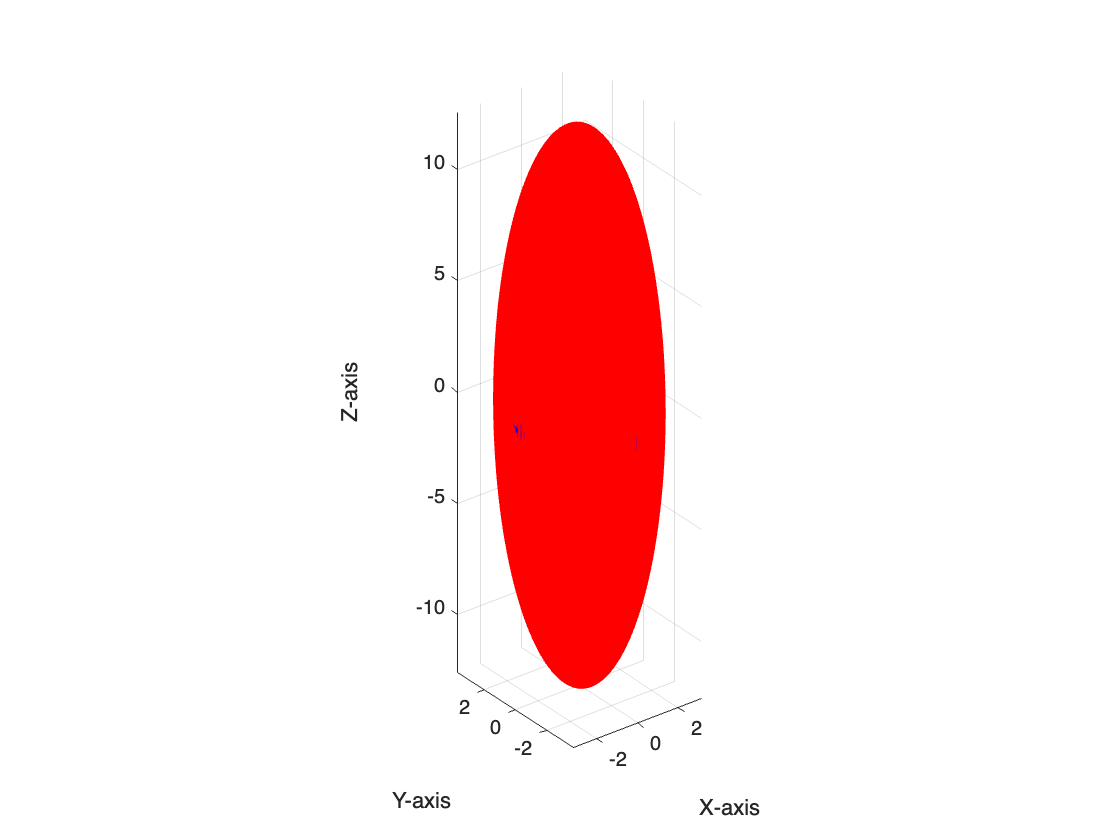


figure;
surf(x_kinetic_ellipsoid, y_kinetic_ellipsoid, z_kinetic_ellipsoid, ...
    'FaceColor', 'b', 'FaceAlpha', 1.0, 'EdgeColor', 'none'); 
hold on;

axis equal;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;

[u, v] = meshgrid(linspace(0, 2*pi, 100), linspace(0, pi, 100));
x_ang_ellipsoid = a_x * cos(u) .* sin(v);
y_ang_ellipsoid = a_y * sin(u) .* sin(v);
z_ang_ellipsoid = a_z * cos(v);
surf(x_ang_ellipsoid, y_ang_ellipsoid, z_ang_ellipsoid, ...
    'FaceColor', 'r', 'FaceAlpha', 1.0, 'EdgeColor', 'none'); 

plot3(w_near_x(1), w_near_x(2), w_near_x(3), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

## Ellipsoids for near z-axis spin

% near x-axis:
h_0 = sqrt(J_xx^2*w_near_z(1)^2 + J_yy^2*w_near_z(2)^2 + J_zz^2*w_near_z(3)^2);
% calculate half-axes:
a_x = sqrt(h_0^2/J_xx^2)

a_x = 1.5710

a_y = sqrt(h_0^2/J_yy^2)

a_y = 1.8483

a_z = sqrt(h_0^2/J_zz^2)

a_z = 6.2841

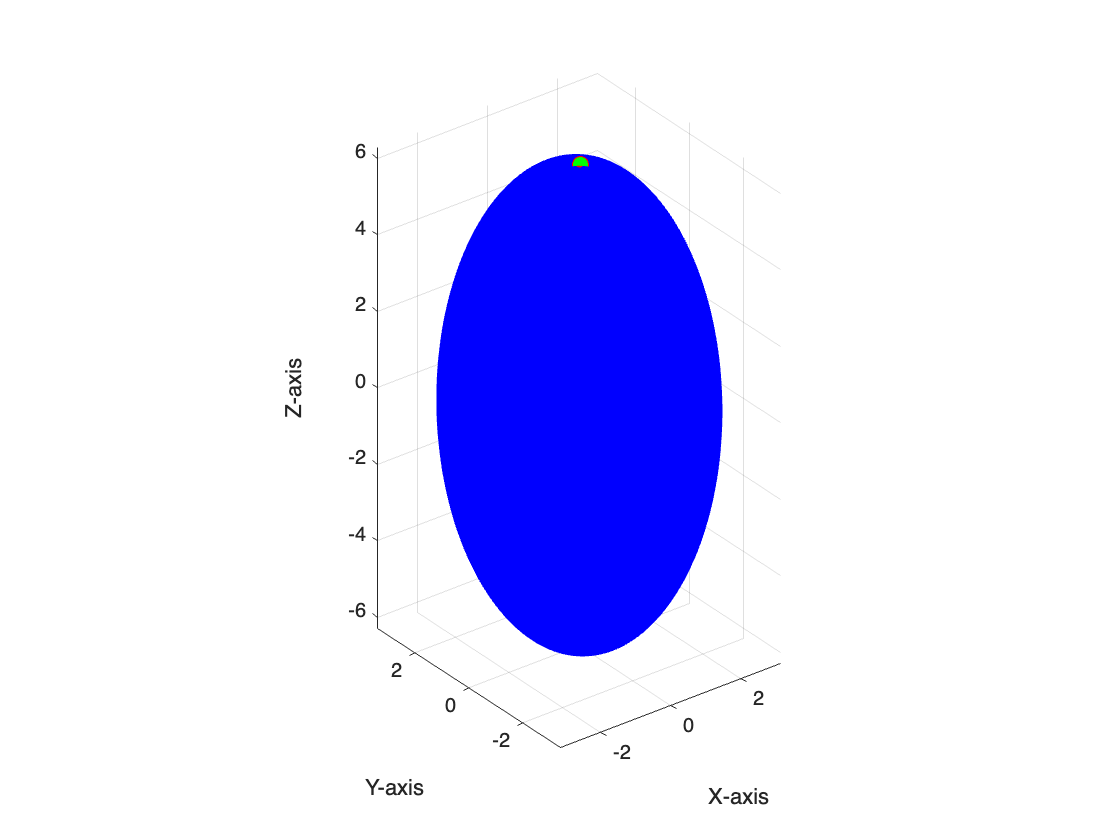


figure;
surf(x_kinetic_ellipsoid, y_kinetic_ellipsoid, z_kinetic_ellipsoid, ...
    'FaceColor', 'b', 'FaceAlpha', 1.0, 'EdgeColor', 'none'); 
hold on;

axis equal;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;

[u, v] = meshgrid(linspace(0, 2*pi, 100), linspace(0, pi, 100));
x_ang_ellipsoid = a_x * cos(u) .* sin(v);
y_ang_ellipsoid = a_y * sin(u) .* sin(v);
z_ang_ellipsoid = a_z * cos(v);
surf(x_ang_ellipsoid, y_ang_ellipsoid, z_ang_ellipsoid, ...
    'FaceColor', 'r', 'FaceAlpha', 1.0, 'EdgeColor', 'none'); 

plot3(w_near_z(1), w_near_z(2), w_near_z(3), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

## Ellipsoids for near y-axis spin

% near x-axis:
h_0 = sqrt(J_xx^2*w_near_y(1)^2 + J_yy^2*w_near_y(2)^2 + J_zz^2*w_near_y(3)^2);
% calculate half-axes:
a_x = sqrt(h_0^2/J_xx^2)

a_x = 2.8964

a_y = sqrt(h_0^2/J_yy^2)

a_y = 3.4076

a_z = sqrt(h_0^2/J_zz^2)

a_z = 11.5857

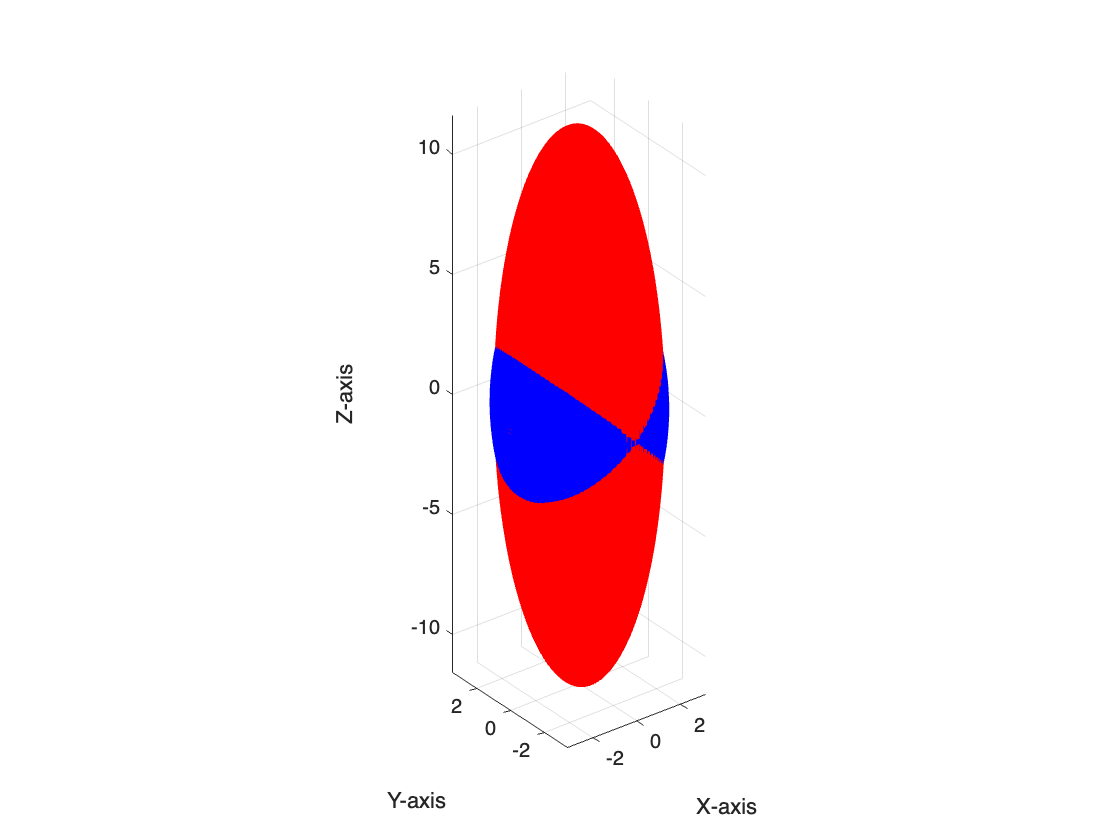


figure;
surf(x_kinetic_ellipsoid, y_kinetic_ellipsoid, z_kinetic_ellipsoid, ...
    'FaceColor', 'b', 'FaceAlpha', 1.0, 'EdgeColor', 'none'); 
hold on;

axis equal;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;

[u, v] = meshgrid(linspace(0, 2*pi, 100), linspace(0, pi, 100));
x_ang_ellipsoid = a_x * cos(u) .* sin(v);
y_ang_ellipsoid = a_y * sin(u) .* sin(v);
z_ang_ellipsoid = a_z * cos(v);
surf(x_ang_ellipsoid, y_ang_ellipsoid, z_ang_ellipsoid, ...
    'FaceColor', 'r', 'FaceAlpha', 1.0, 'EdgeColor', 'none'); 

plot3(w_near_y(1), w_near_y(2), w_near_y(3), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

## Simulate euler equations:

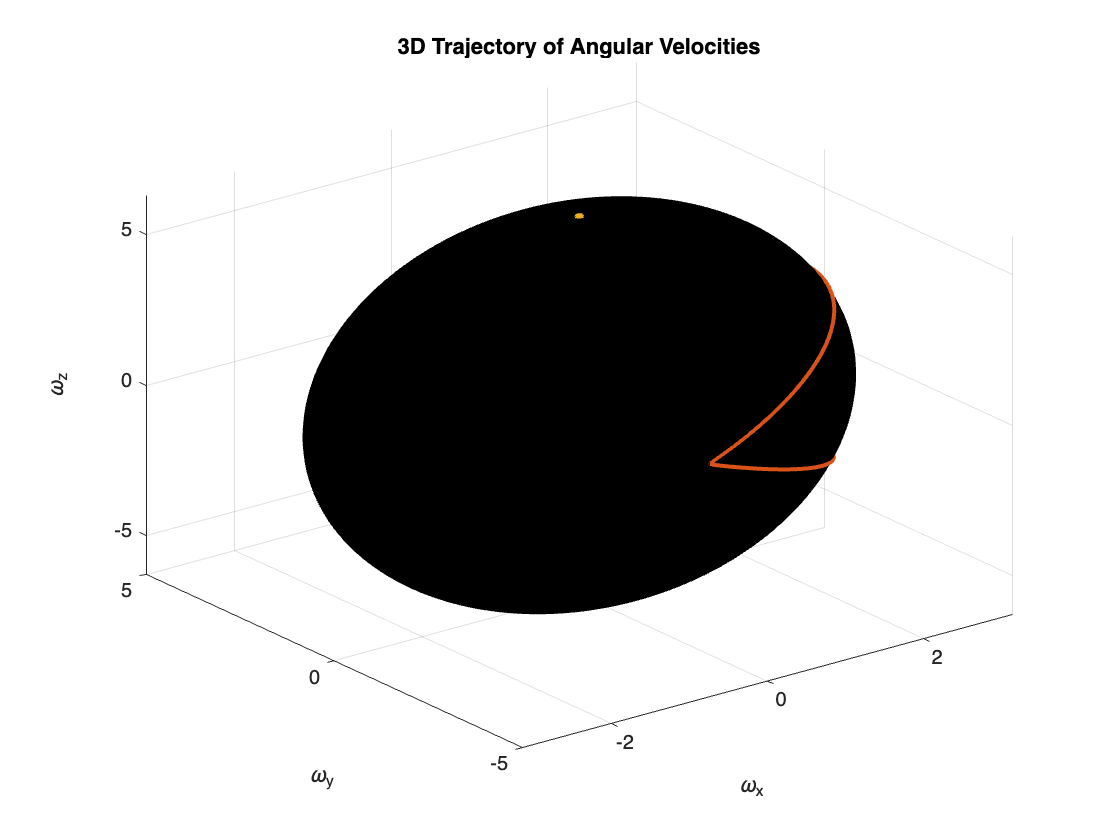

% w_x_dot = (1/J_xx)*w_y*w_z*(J_zz-J_yy)
% w_y_dot = (1/J_yy)*w_x*w_z*(J_xx-J_zz)
% w_z_dot = (1/J_zz)*w_x*w_y*(J_yy-J_xx)

function w_dot = angular_velocity(t, w)
    J_xx = 100/12;
    J_yy = 85/12;
    J_zz = 25/12;
    w_dot = [(1/J_xx) * w(2) * w(3) * (J_zz - J_yy); 
             (1/J_yy) * w(1) * w(3) * (J_xx - J_zz);
             (1/J_zz) * w(1) * w(2) * (J_yy - J_xx)
             ];
end

tspan = linspace(0, 10, 300);
% near x-axis
w0 = [w_near_x];
[t, w_traj_near_x] = ode45(@angular_velocity, tspan, w0);
% near y-axis
w0 = [w_near_y];
[t, w_traj_near_y] = ode45(@angular_velocity, tspan, w0);
% near z-axis
w0 = [w_near_z];
[t, w_traj_near_z] = ode45(@angular_velocity, tspan, w0);

figure;
hold on;
surf(x_kinetic_ellipsoid, y_kinetic_ellipsoid, z_kinetic_ellipsoid, ...
    'FaceColor', '#000', 'FaceAlpha', 1.0, 'EdgeColor', 'none'); 
plot3(w_traj_near_x(:, 1), w_traj_near_x(:, 2), w_traj_near_x(:, 3), 'LineWidth', 2);
plot3(w_traj_near_y(:, 1), w_traj_near_y(:, 2), w_traj_near_y(:, 3), 'LineWidth', 2);
plot3(w_traj_near_z(:, 1), w_traj_near_z(:, 2), w_traj_near_z(:, 3), 'LineWidth', 2);
hold off;

grid on;
xlabel('\omega_x');
ylabel('\omega_y');
zlabel('\omega_z');
title('3D Trajectory of Angular Velocities');
view(3);

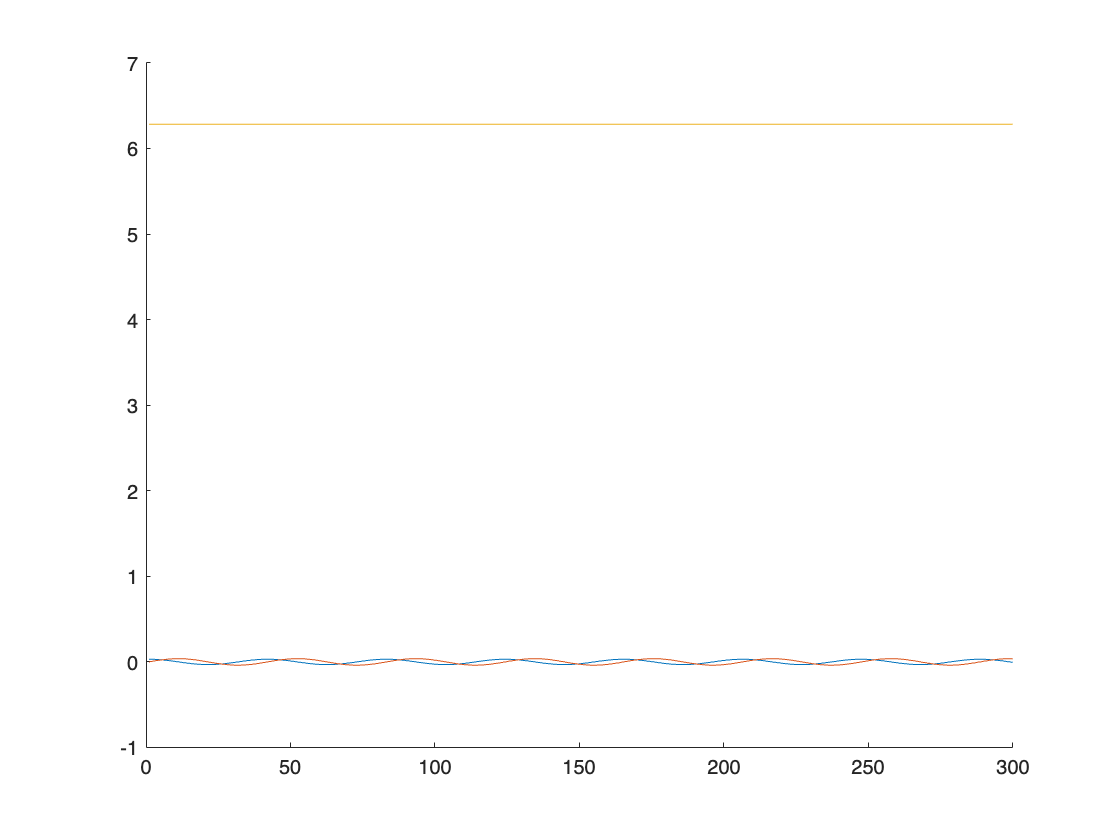

figure;
hold on;
plot(w_traj_near_z(:, 1));
plot(w_traj_near_z(:, 2));
plot(w_traj_near_z(:, 3));
hold off;

## Simulate attitudes

function euler_dot = euler_rates(t, theta_curr, w_traj)
    w = interp1(w_traj(:,1), w_traj(:,2:4), t);
    
    T = [1, sin(theta_curr(1))*tan(theta_curr(2)), cos(theta_curr(1))*tan(theta_curr(2));
         0, cos(theta_curr(1)), -sin(theta_curr(1));
         0, sin(theta_curr(1))/cos(theta_curr(2)), cos(theta_curr(1))/cos(theta_curr(2))];
    
    euler_dot = T * [w(1); w(2); w(3)];
end

theta0 = [0; 0; 0];
[t, theta_near_x] = ode45(@(t, theta) euler_rates(t, theta, [tspan' w_traj_near_x]), tspan, theta0);
[t, theta_near_y] = ode45(@(t, theta) euler_rates(t, theta, [tspan' w_traj_near_y]), tspan, theta0);
[t, theta_near_z] = ode45(@(t, theta) euler_rates(t, theta, [tspan' w_traj_near_z]), tspan, theta0);


## Plot angles

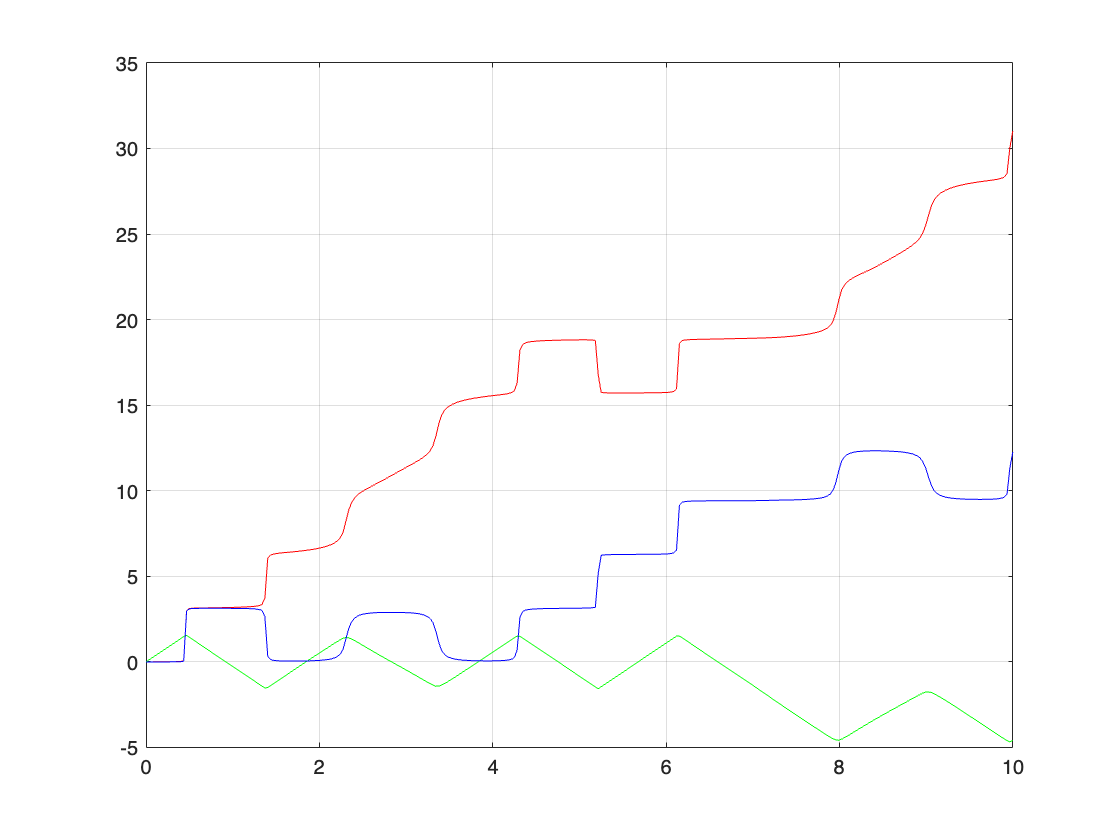

phi = theta_near_y(:, 1);
theta = theta_near_y(:, 2);
psi = theta_near_y(:, 3);

figure;
plot(t, phi, 'r', t, theta, 'g', t, psi, 'b');
grid on;

L = 5; 
W = 10;
H = 20; 


## Animate

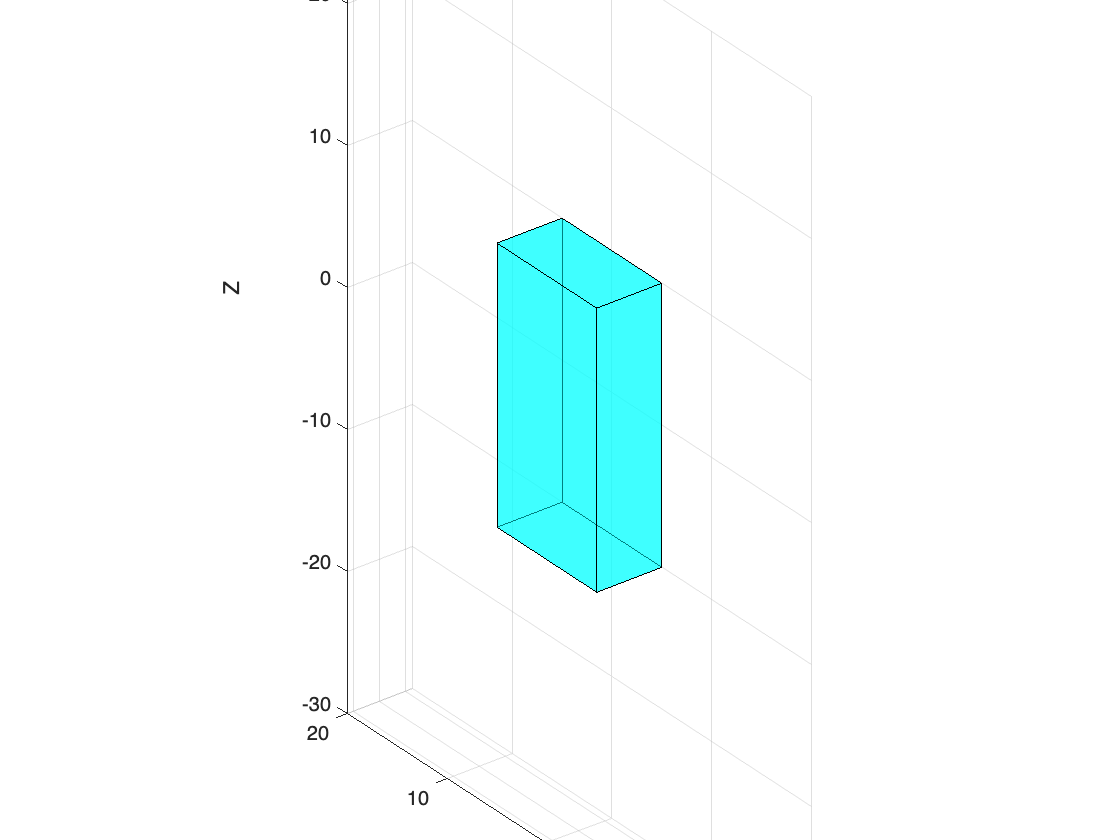

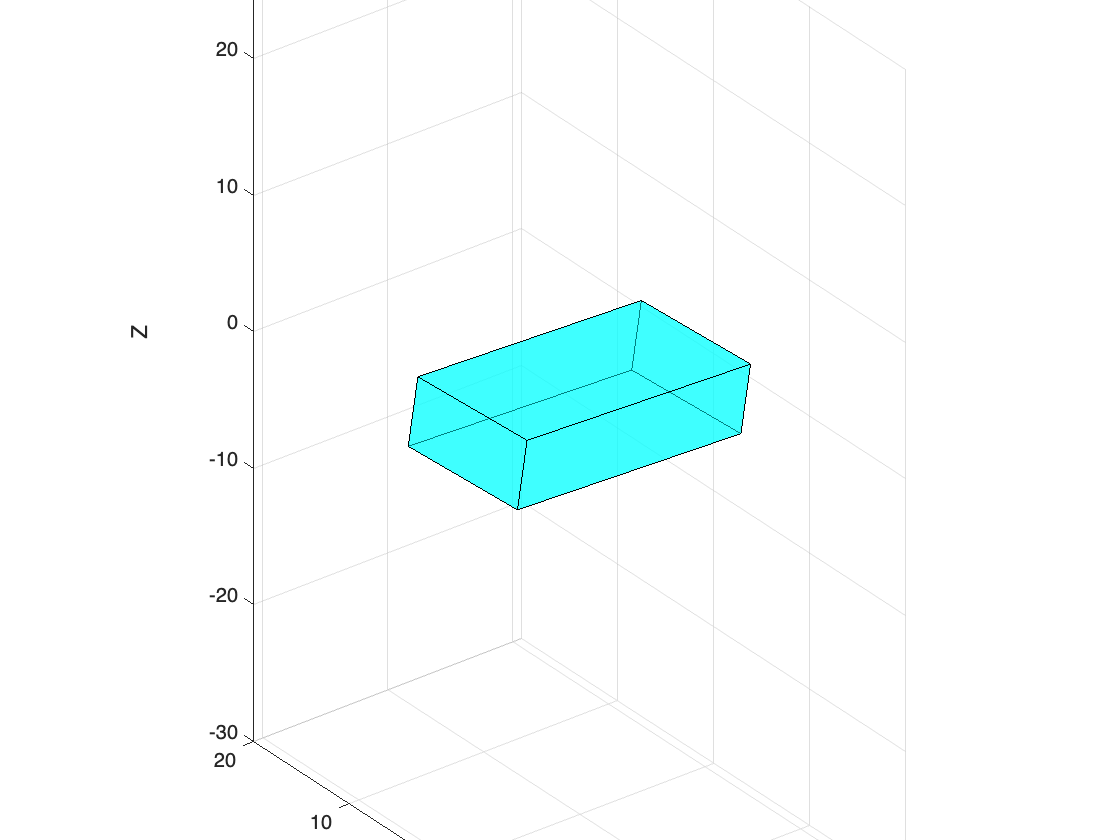


%brukt ChatGPT for å få til murstein-plottingen

vertices = [ 
    L/2, W/2, H/2; 
    L/2, -W/2, H/2; 
    L/2, -W/2, -H/2;
    L/2, W/2, -H/2;
   -L/2, W/2, H/2;
   -L/2, -W/2, H/2; 
   -L/2, -W/2, -H/2;
   -L/2, W/2, -H/2; 
];

faces = [
    1 2 3 4; 
    5 6 7 8;
    1 2 6 5;
    4 3 7 8;
    1 4 8 5;
    2 3 7 6;
];

figure;
xlim([-L-10, L+10]);
ylim([-W-10, W+10]);
zlim([-H-10, H+10]);
set(gca, 'CameraViewAngleMode', 'manual');

axis equal;
grid on;
hold on;
xlabel('X'); ylabel('Y'); zlabel('Z');
view(3);

numVertices = size(vertices, 1);
trajectories = zeros(length(t), numVertices, 3);

for i = 1:length(t)
    R_z = [cos(psi(i)), -sin(psi(i)), 0;
           sin(psi(i)),  cos(psi(i)), 0;
           0,            0,           1];
    
    R_y = [cos(theta(i)), 0, sin(theta(i));
           0,             1, 0;
          -sin(theta(i)), 0, cos(theta(i))];
    
    R_x = [1, 0,            0;
           0, cos(phi(i)), -sin(phi(i));
           0, sin(phi(i)),  cos(phi(i))];
    
    R = R_z * R_y * R_x;
    rotated_vertices = (R * vertices')';
    cla;
    patch('Vertices', rotated_vertices, 'Faces', faces, ...
          'FaceColor', 'cyan', 'EdgeColor', 'black', 'FaceAlpha', 0.5);
    title(sprintf('Time: %.2f s', t(i)));
    drawnow;
    
    pause(0.002);
    trajectories(i, :, :) = rotated_vertices;

end

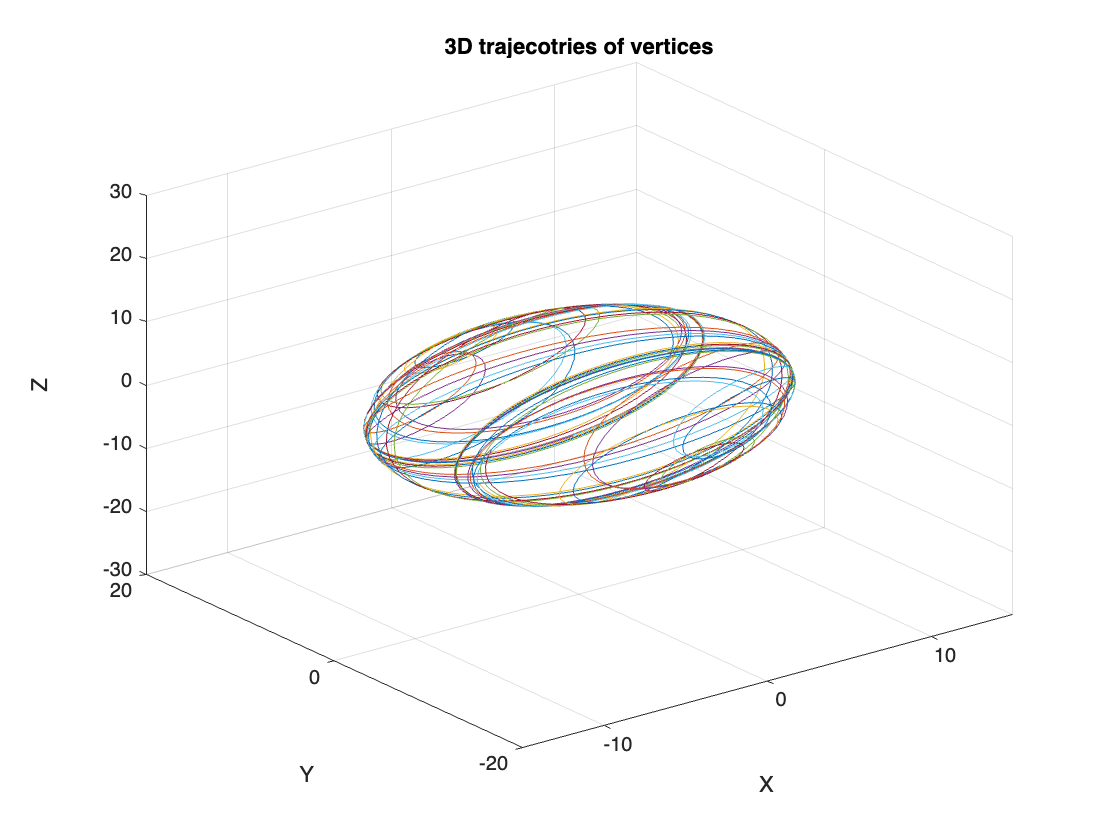

figure;
hold on;
grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
xlim([-L-10, L+10]);
ylim([-W-10, W+10]);
zlim([-H-10, H+10]);
view(3);

for v = 1:numVertices
    traj = squeeze(trajectories(:, v, :));
    plot3(traj(:, 1), traj(:, 2), traj(:, 3));
end

title('3D trajecotries of vertices');